## Transfer function from Pitch to X position

Note: Disable position control in the simulink model before running

model = 'DroneModel'

model = 'DroneModel'

% We then load and open the system
load_system(model);
open_system(model);


% We define the points in the model from which to linearize
ios(1) = linio(strcat(model,'/Drone'),7,'openoutput');
% ios(2) = linio(strcat(model, '/Position controller'),2,'openinput');
ios(2) = linio(strcat(model, '/Pitch_ref'),1,'openinput');
% Attach these points to the model
setlinio(model,ios);
% Use the snapshot time(s) of 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% Obtain the transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
Gx = minreal(tf(num, den))

Gx =
 
                0.3316 s^2 + 8.291 s - 2.682e-06
  -------------------------------------------------------------
  s^5 + 6.067e06 s^4 + 9.203e12 s^3 + 4.602e14 s^2 + 5.752e15 s
 
Continuous-time transfer function.
Model Properties


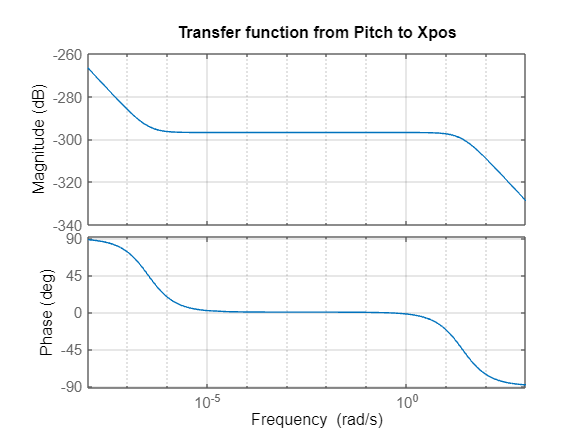


% Bode plot of the transfer function
figure();
bode(Gx)
grid on
title('Transfer function from Pitch to Xpos')

## Transfer function from Roll to Y position

model = 'DroneModel'

model = 'DroneModel'

% We then load and open the system
load_system(model);
open_system(model);


% We define the points in the model from which to linearize
ios(1) = linio(strcat(model,'/Drone'),8,'openoutput');
% ios(2) = linio(strcat(model, '/Position controller'),1,'openinput');
ios(2) = linio(strcat(model, '/Roll_ref'),1,'openinput');
% Attach these points to the model
setlinio(model,ios);
% Use the snapshot time(s) of 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% Obtain the transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
Gy = minreal(tf(num, den))

Gy =
 
                   -5.641e15
  -------------------------------------------
  s^4 + 3.034e06 s^3 + 7.584e07 s^2 + 24.52 s
 
Continuous-time transfer function.
Model Properties


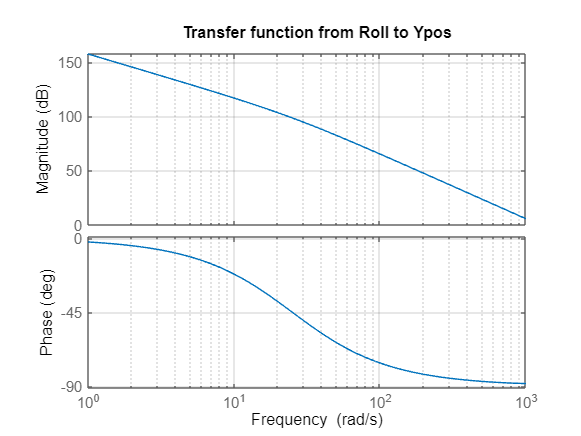


% Bode plot of the transfer function
figure();
bode(Gy)
grid on
title('Transfer function from Roll to Ypos')

## Design PID for Y position

s = tf('s');   
[M,P,w_out] = bode(Gy);            % Get magnitude and phase of G
M = mag2db(squeeze(M));
P = squeeze(P);
% Define Ni, alpha and gamma_M
N_i = 3;
alpha = 0.3;
gamma_M = 60;
% Define phase contributions from PI and P-Lead and phase of G at new
% cross-over frequency.
phi_i = rad2deg(-atan(1/N_i));
phi_m = rad2deg(asin((1 - alpha)/(1 + alpha)));
phi_G = -180 + gamma_M - phi_i - phi_m;

i_c = find(P <= phi_G,1);   % Get the index of the new cross-over frequency
omega_c = w_out(i_c);       % Get omega_c

% PI controller time constant and transfer function
tau_i = N_i/omega_c;
C_PI = (1 + 1/(tau_i*s));

Error using  / 
In "SYS1/SYS2", the model SYS2 must have the same number of inputs as outputs.


% P-Lead controller time constant and transfer function
tau_d = 1/(omega_c*sqrt(alpha));
C_D = (tau_d*s + 1)/(alpha*tau_d*s + 1);

% Open-loop transfer function
G_ol = minreal(C_PI*C_D*G);

% P-controller gain
K_P = 1/abs(freqresp(G_ol,omega_c));

G_cl_P = K_P*G/(1 + K_P*G);                     % Closed-loop with PI-Lead controller
step(G_cl_P,0:0.01:T)